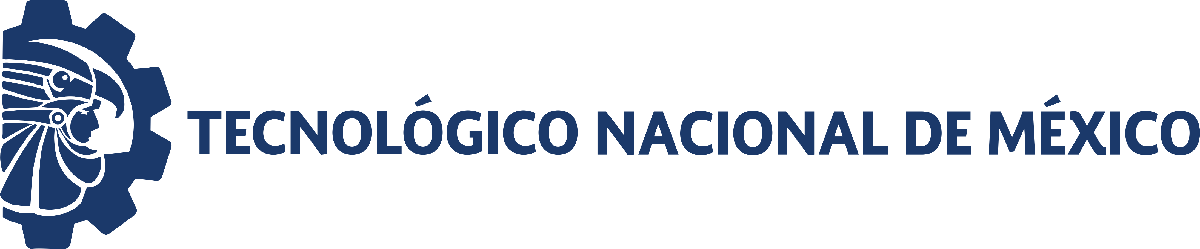                                 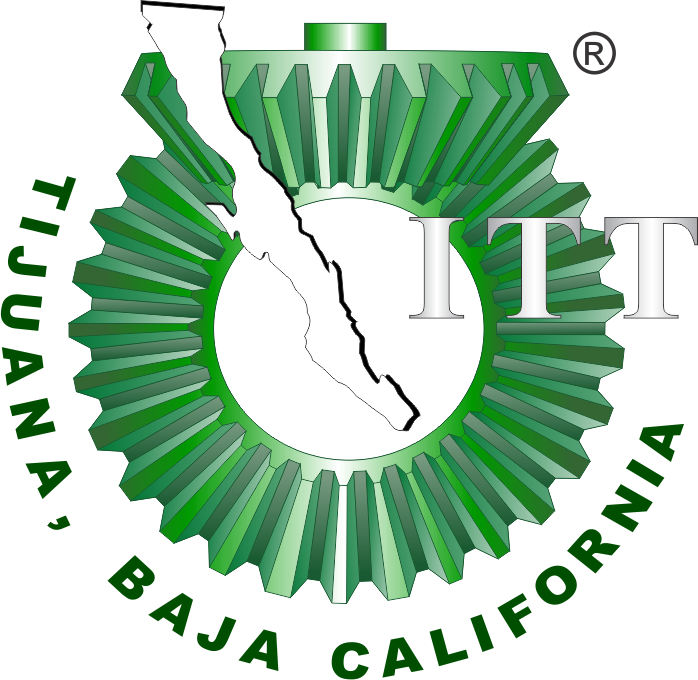

# Práctica 3: Sistema Musculoesqueletico 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

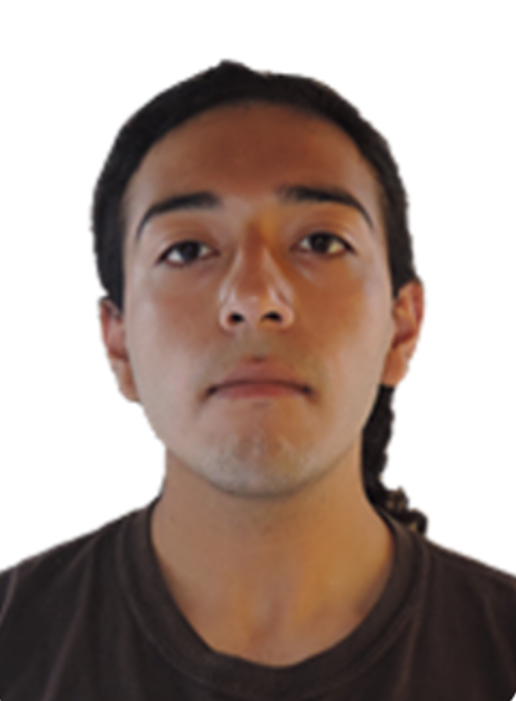

[Foto]

Nombre del alumno: **Andres Preciado Hernandez **

Número de control: **21210469**

Correo institucional: **l21210469@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'SistemaD';
open_system(file);
parameters.StopTime = tend; 
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

## Respuesta del lazo abierto

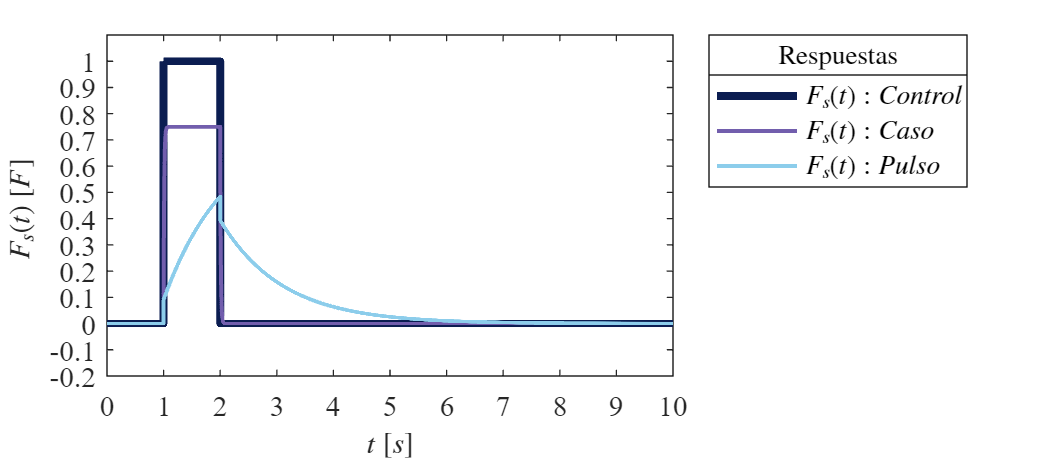

set_param('SistemaD/Fs','Amplitude','1');
set_param('SistemaD/Fs','Period','10');
set_param('SistemaD/Fs','PulseWidth','10');
set_param('SistemaD/Fs','Phasedelay','1');
x = sim(file, parameters);
plotsignals(x.t,x.Fs,x.Fs1,x.Fs2);

## Respuesta del lazo cerrado

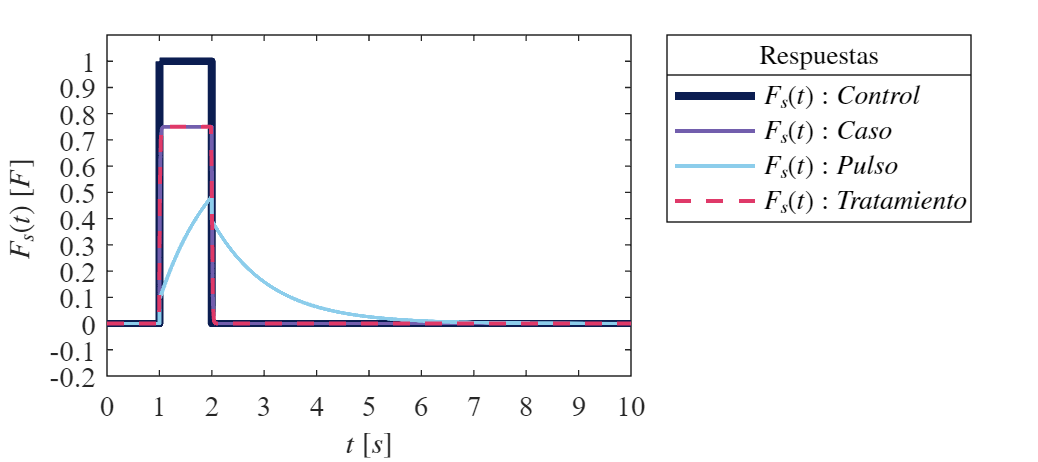


set_param('SistemaD/Fs','Amplitude','1');
set_param('SistemaD/Fs','Period','10');
set_param('SistemaD/Fs','PulseWidth','10');
set_param('SistemaD/Fs','Phasedelay','1');
x1 = sim(file, parameters);
plotsignal(x1.t,x1.Fs,x1.Fs1,x1.Fs2,x1.Fs3);

## Respuesta a la rampa

## Respuesta a la función sinusoidal

## Funcion: Respuesta a las Señales 

function plotsignals (t,Fs, Fs1, Fs2)
set(figure(), 'Color', 'w');
    set(gcf, 'units', 'centimeters', 'position', [1,1,18,8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    hold on; grid off; box on; 
    mycolors = [011,029,081;
                114,094,173;
                140,205,235;
                223, 57, 105;
                127, 76, 165;
                5, 127, 109;
                ]/255;
    colororder(mycolors);
    p = plot(t, Fs, '-', t, Fs1, '-', t, Fs2, '-'...
        ,'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
    set(p(1), 'LineWidth', 3);
    L = legend('$F_{s}(t): Control$','$F_{s}(t): Caso$','$F_{s}(t): Pulso$');
       
    title(L,'Respuestas', 'FontSize', 10);
    set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11);
     ylabel('$F_s(t)$ $[F]$ ', 'Interpreter', 'Latex', 'FontSize', 11);
    xlim([0, 10]); xticks(0:1:10); 
    ylim([-0.2, 1.1]); yticks(-0.2:0.1:1); 
    exportgraphics(gcf, 'Musculoesqueletico.pdf', 'ContentType', 'vector')
    exportgraphics(gcf, 'Musculoesqueletico.png', 'ContentType', 'vector')
end

function plotsignal(t,Fs,Fs1,Fs2,Fs3)
set(figure(), 'Color', 'w');
    set(gcf, 'units', 'centimeters', 'position', [1,1,18,8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    hold on; grid off; box on; 
    mycolors = [011,029,081;
                114,094,173;
                140,205,235;
                223, 57, 105;
                127, 76, 165;
                5, 127, 109;
                ]/255;
    colororder(mycolors);
    p = plot(t, Fs, '-', t, Fs1, '-', t, Fs2, '-',t, Fs3, '--',...
      'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
    set(p(1), 'LineWidth', 3);
 L = legend('$F_{s}(t): Control$','$F_{s}(t): Caso$','$F_{s}(t): Pulso$','$F_{s}(t): Tratamiento$');
    title(L,'Respuestas', 'FontSize', 10);
    set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11);
    ylabel('$F_s(t)$ $[F]$ ', 'Interpreter', 'Latex', 'FontSize', 11);
    xlim([0, 10]); xticks(0:1:10) 
    ylim([-0.2, 1.1]); yticks(-0.2:0.1:1) 
    exportgraphics(gcf, 'Musculoesqueletico1.pdf', 'ContentType', 'vector')
    exportgraphics(gcf, 'Musculoesqueletico1.png', 'ContentType', 'vector')
end
